% Parameterize the arm
rho = 0.0254; % M, Radius

% Orientation of muscles in world frame:
tilt_angle = deg2rad(15);

% Orientation of base curve (x = up):
R_g_o = eul2rotm([0, -pi/2, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(R_g_o, [0 0 0]); % Base-curve frame
g_muscles = Arm3D.generate_g_muscles(rho, g_o, 4, tilt_angle);

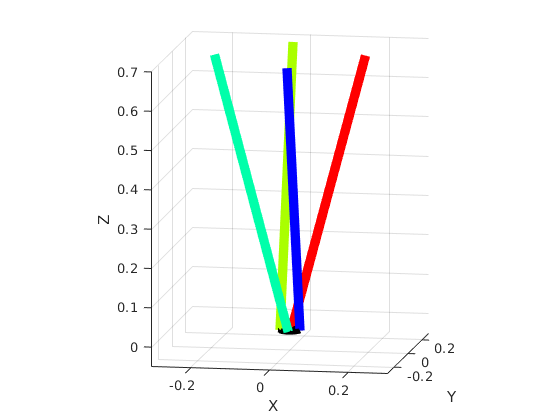

l_0 = 40 * 0.0254; % Default length

%helical_arm_obj = Arm3D(g_o, g_muscles, l_0);
helical_arm_obj = HelicalArm(g_o, g_muscles, l_0);
helical_arm_obj.rho = rho;

fig = figure();
ax = axes(fig);
line_options_muscles = struct("LineWidth", 7);
line_options_circles = struct("LineWidth", 4);
helical_arm_obj.initialize_plotting(ax, ...
    "line_options_circles", line_options_circles, ...
    "line_options_muscles", line_options_muscles, ...
    "resolution", 40);

border_length_cm = 60;
axis equal
xlim(ax, [-0.5, 0.5] * border_length_cm/100);
ylim(ax, [-0.5, 0.5] * border_length_cm/100);
zlim(ax, [-0.05, 0.75])
set(fig, 'Visible', true)

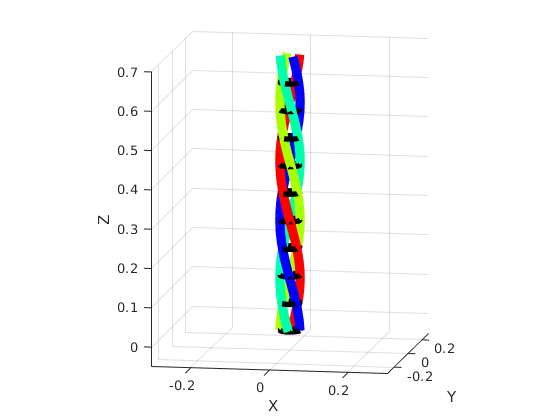

l_A = 40; % Red
l_B = 40;  % Green
l_C = 40; % Cyan
l_D = 40;  % Blue

v_l = [l_A; l_B; l_C; l_D];
helical_arm_obj.update_arm(v_l * 0.0254);

helical_arm_obj.plot_base_curve = true;

contraction_period = 4;
% phase_shift = contraction_period/2; % Sequential
phase_shift = contraction_period/4; % Concurrent

t_end = phase_shift*4;
fps = 24;
t = linspace(0, t_end, fps * t_end);

period = t_end;
l_max = 40 * 0.0254;
l_min = 28 * 0.0254;
delta_l = l_max - l_min;

% We define a full contraction cycle as starting and ending at 3 std_dev away (99.9%). The total periodhas 6 std_devs
std_dev = 0.5*contraction_period/3;

% Contraction function
% A bell curve with amplitude delta_l, and std_dev as defined above
% Phase offset by start time and half of the period
f_contraction = @(t_start) (l_max - delta_l * exp(-0.5 * ((t - t_start - contraction_period/2)/std_dev).^2)); % This is a mess yikes
f_contraction_peak = @(t_peak) (delta_l * exp(-0.5 * ((t - t_peak)/std_dev).^2)); % This is a mess yikes

%{
l_A = f_contraction(0);
l_B = f_contraction(phase_shift);
l_C = f_contraction(phase_shift*2);
l_D = f_contraction(phase_shift*3);
%}

l_D = l_max - f_contraction_peak(-phase_shift) - f_contraction_peak(phase_shift*3);
l_A = l_max - f_contraction_peak(0) - f_contraction_peak(phase_shift*4);
l_B = l_max - f_contraction_peak(phase_shift) - f_contraction_peak(phase_shift*5);
l_C = l_max - f_contraction_peak(phase_shift*-2) - f_contraction_peak(phase_shift*2) - f_contraction_peak(phase_shift*6);

mat_l = [l_A(:) l_B(:) l_C(:) l_D(:)];

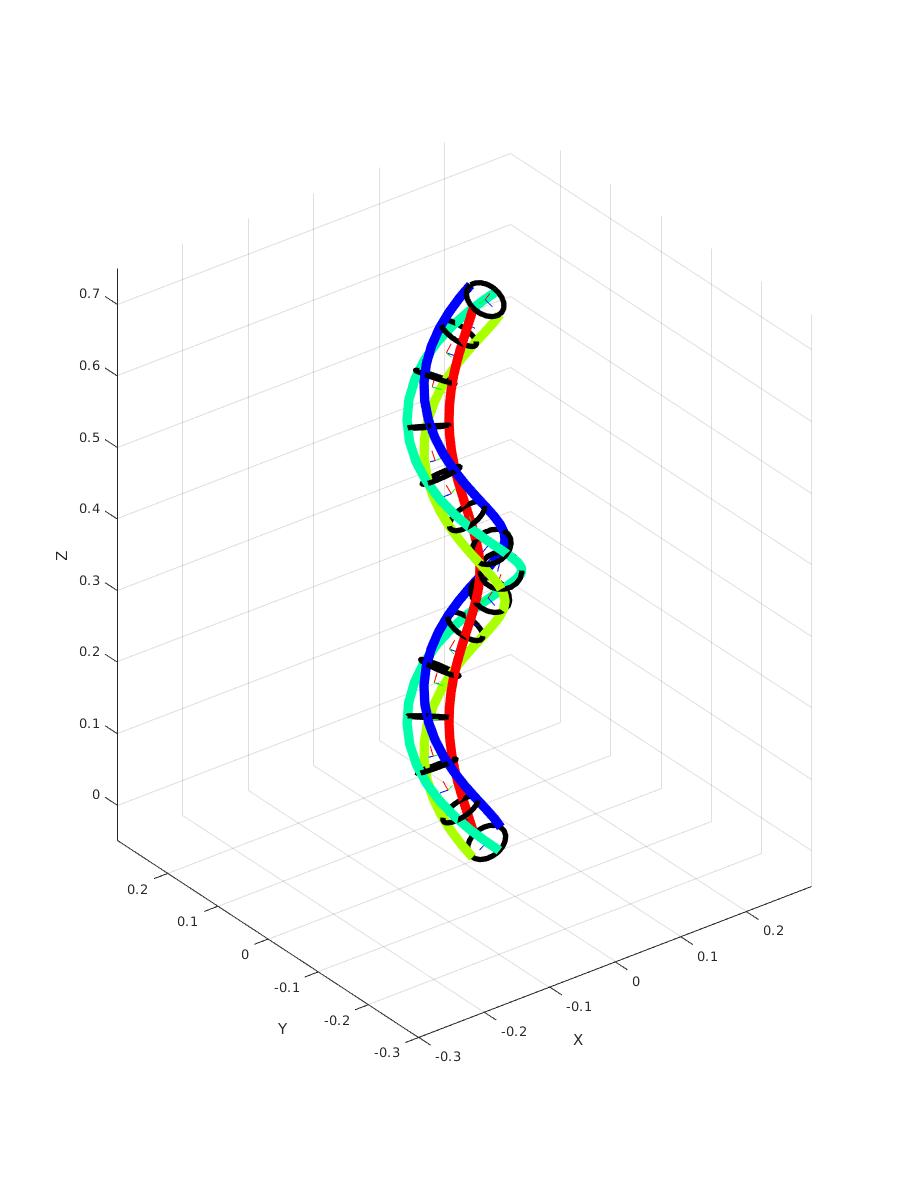

animator = Animator(fig, length(t));

% Pre-allocate analysis metrics
mat_radius_vectors = zeros(length(t), 3);
v_winding_radii = zeros(size(t));
v_pitch = zeros(size(t));

for i = 1 : length(t)
    v_l_i = mat_l(i, :)';
    helical_arm_obj.update_arm(v_l_i);
    
    % Save current helix parameters
    if class(helical_arm_obj) == "HelicalArm"
        mat_radius_vectors(i, :) = helical_arm_obj.radius_vector_o;
        v_winding_radii(i) = norm(helical_arm_obj.radius_vector_o);
        v_pitch(i) = helical_arm_obj.pitch;
    end
    
    animator.get_frame();
    drawnow
end

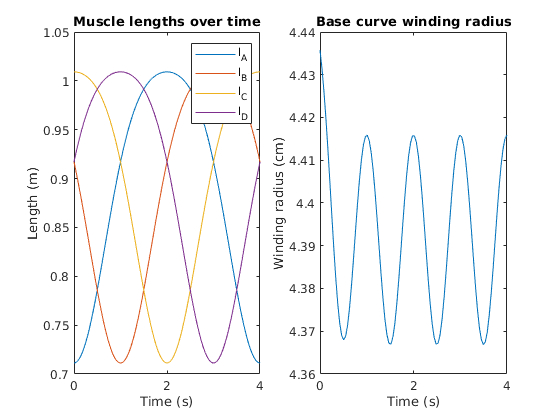

figure();

subplot(1, 2, 1)
plot(t, mat_l);
legend(["l_A", "l_B", "l_C", "l_D"])
title("Muscle lengths over time")
xlabel("Time (s)")
ylabel("Length (m)")


subplot(1, 2, 2)
plot(t, v_winding_radii * 100)
xlabel("Time (s)")
ylabel("Winding radius (cm)")
title("Base curve winding radius")

animator.save_gif("frame_rate", fps);